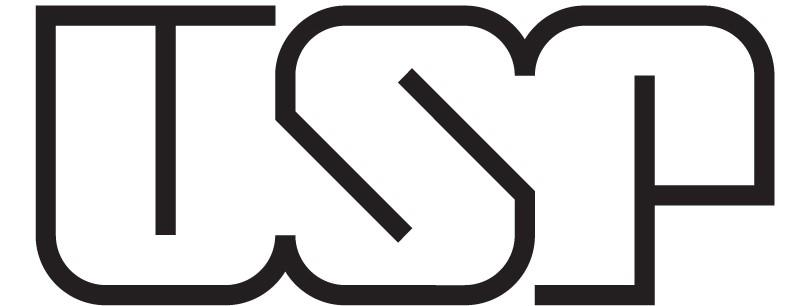

**UNIVERSIDADE DE SÃO PAULO**

**ESCOLA DE ENGENHARIA DE SÃO CARLOS**

**SEM0172 - Vibrações Mecânicas**

***Projeto 1***

**Data:** 08/05/2024

João Vítor de Oliveira - 12611734

# Projeto - Simulação de resposta de sistemas de 1 GDL

## Equação do movimento para o sistema

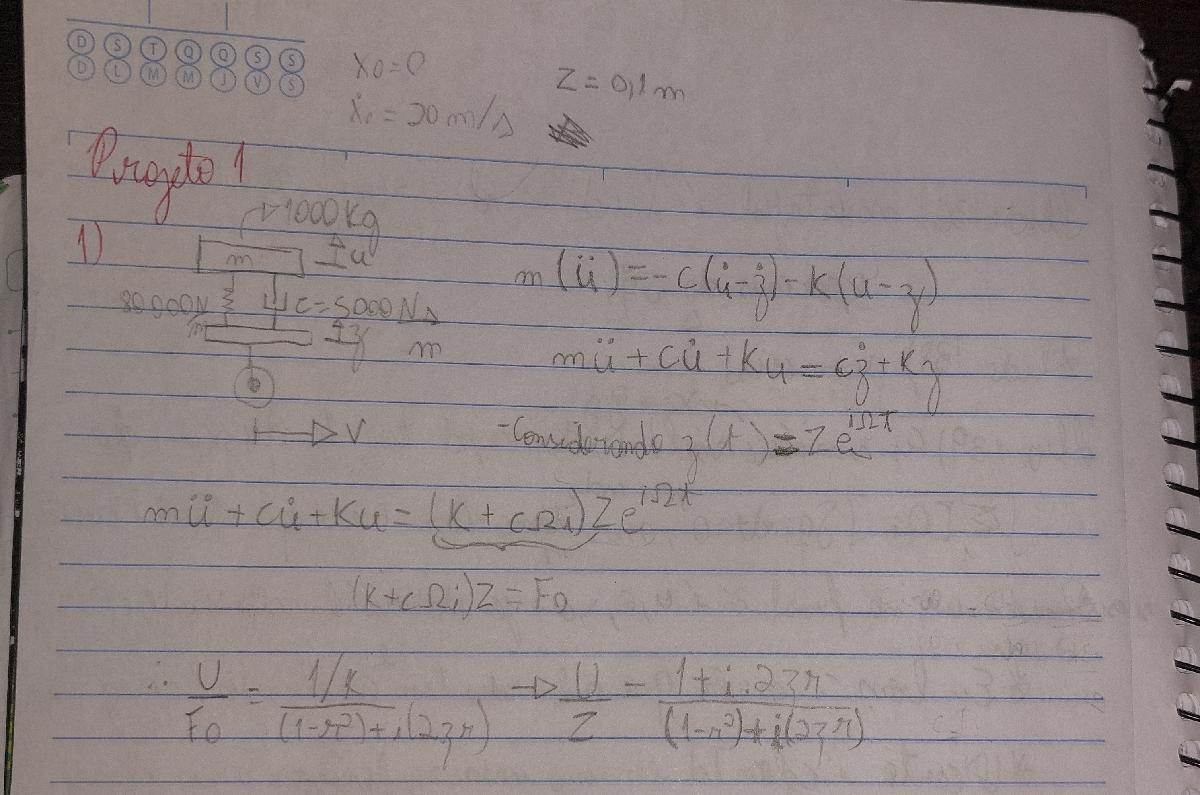

## Frequência natural e fator de amortecimento

m = 1000;
c = 5000;
k = 80000;
x0 = [20, 0];
t = [0:0.01:57.6/20];
omega = (k/m)^0.5 %rad/s

omega = 8.9443

zeta = c/(2*(m*k)^0.5)

zeta = 0.2795

    Logo, temos um movimento subamortecido!

## Resposta transitória (impulsiva) e em frequência (FRF) com excitação na base

    Tendo como função transferência:

den = [m,c,k];
num_sis = [c,k];
sys1 = tf(num_sis,den)

sys1 =
 
       5000 s + 80000
  -------------------------
  1000 s^2 + 5000 s + 80000
 
Continuous-time transfer function.



    Podemos visualizar a resposta do sistema ao impulso de forma muito simples:

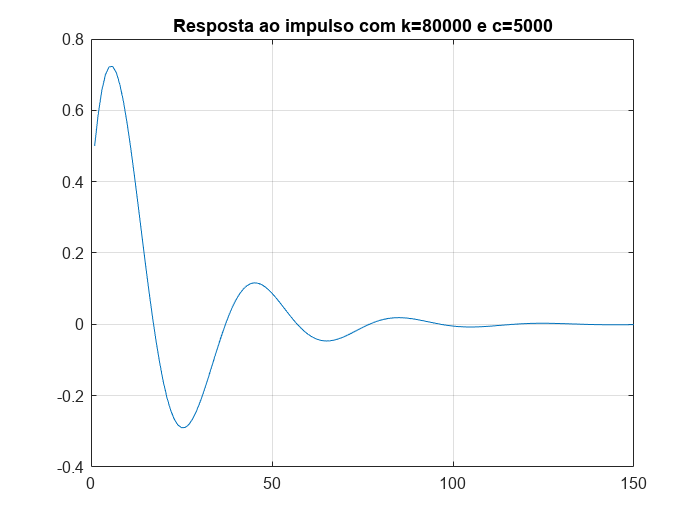

yimpulse = 0.1*impulse(sys1);
figure(1)
p1 = plot(yimpulse);
grid
title('Resposta ao impulso com k=80000 e c=5000')

    Agora, podemos visualizar o gráfico da resposta em frequência:

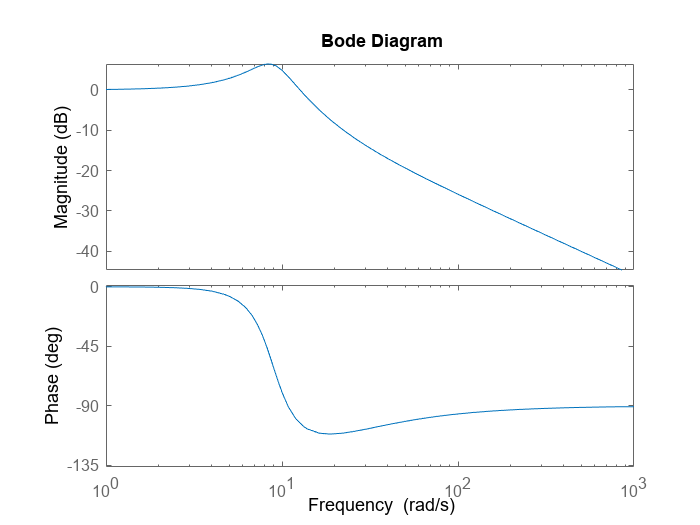

figure(6)
bode(sys1)

## Resposta quando o veículo passa pelas diferentes pistas sugeridas

    Agora, chegou o momento de supormos alguns valores para nossos estudos, primeiro, devemos propor um estado inicial de nosso sistema, e então, foi proposto o valor de 20 m/s para velocidade inicial e 0 m para deslocamento inicial:

x0 = [20, 0];

    Em relação à pista, foi proposta uma amplitude de 0.1 metros (para o valor da pista senoidal, o valor pico a pico é de 0.2 m) e um comprimento de 3.6 m, conforme a imagem abaixo:

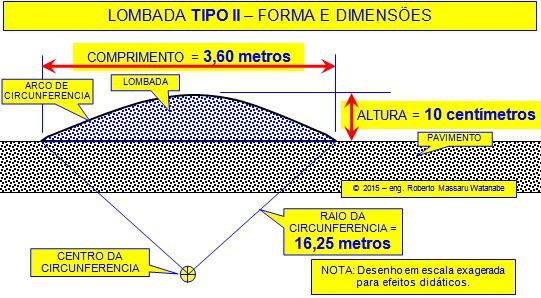

    Agora, com esses dados, podemos visualizar o movimento da base do sistema e do próprio sistema em si:

zsen = 0.1*sin(2*pi()*t/0.36);
ysen = lsim(sys1,zsen,t,x0);
figure(2);
subplot(1,3,1);
p2 = plot(t,ysen,"b");
hold on 
subplot(1,3,1);
p3 = plot(t,zsen,"r");
ylim([-0.3, 0.3]);
grid
legend('y(t)','z(t)')
title('Entrada Senoidal')
xlabel('tempo [s]')
ylabel('saída y [m]')

    De forma similar para a pista parabólica:

t1 = [0.01:0.01:3.6/20];

z1parab = [-20*t1.*(20*t1-3.6)*0.0308641976 zeros(1,length(20*t1))];
zparab = [z1parab z1parab z1parab z1parab z1parab z1parab z1parab ...
    -20*t1.*(20*t1-3.6)*0.0308641976 zeros(1,length(t) - 15*length(20*t1))];
yparab = lsim(sys1,zparab,t,x0);

subplot(1,3,2);
p4 = plot(t,yparab,"b");
hold on 
subplot(1,3,2);
p5 = plot(t,zparab,"r");
ylim([-0.3, 0.3]);
grid
legend('y(t)','z(t)')
title('Entrada Parabólica')
xlabel('tempo [s]')
ylabel('saída y [m]')

Para a pista trapezoidal:

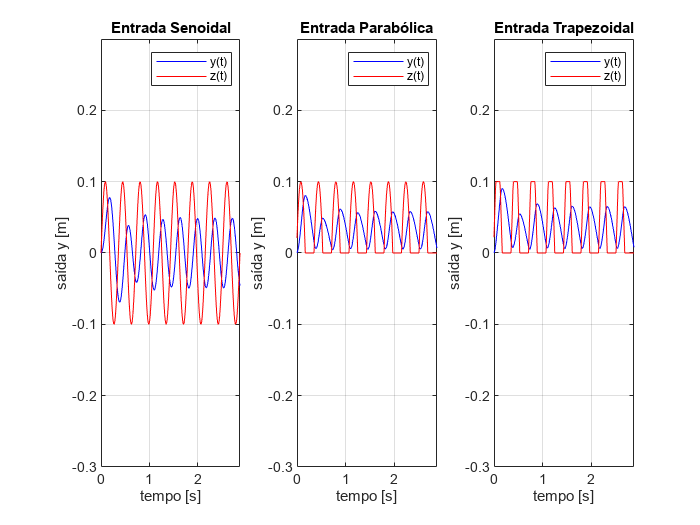

ztrap = [0.1*trapmf(t1,[0 0.9/20 2.7/20 3.6/20]) zeros(1,length(t1)) ...
    0.1*trapmf(t1,[0 0.9/20 2.7/20 3.6/20]) zeros(1,length(t1)) ...
    0.1*trapmf(t1,[0 0.9/20 2.7/20 3.6/20]) zeros(1,length(t1)) ...
    0.1*trapmf(t1,[0 0.9/20 2.7/20 3.6/20]) zeros(1,length(t1)) ...
    0.1*trapmf(t1,[0 0.9/20 2.7/20 3.6/20]) zeros(1,length(t1)) ...
    0.1*trapmf(t1,[0 0.9/20 2.7/20 3.6/20]) zeros(1,length(t1)) ... 
    0.1*trapmf(t1,[0 0.9/20 2.7/20 3.6/20]) zeros(1,length(t1)) ...
    0.1*trapmf(t1,[0 0.9/20 2.7/20 3.6/20]) zeros(1,length(t)-15*length(t1))];
ytrap = lsim(sys1,ztrap,t,x0);

subplot(1,3,3);
p6 = plot(t,ytrap,"b");
hold on 
subplot(1,3,3);
p7 = plot(t,ztrap,"r");
ylim([-0.3, 0.3]);
grid
legend('y(t)','z(t)')
title('Entrada Trapezoidal')
xlabel('tempo [s]')
ylabel('saída y [m]')

## Efeito dos parâmetros da suspensão (k e c) nas respostas

    Agora, serão plotadas as respostas ao impulso de outros 2 valores de k (arbitrários), mantendo-se o c constante e de 2 valores de c (arbitrários), mantendo-se k constante, e nos mesmos gráficos, serão comparados os gráficos dos novos valores com o gráfico de k e c dados pelo exercício:

%C menor
c1 = 2500;
k1 = 80000;

den1 = [m,c1,k1];
num_sis1 = [c1,k1];
sys11 = tf(num_sis1,den1)

sys11 =
 
       2500 s + 80000
  -------------------------
  1000 s^2 + 2500 s + 80000
 
Continuous-time transfer function.



yimpulse1 = 0.1*impulse(sys11);


%C maior
c2 = 7500;
k2 = 80000;

den2 = [m,c2,k2];
num_sis2 = [c2,k2];
sys12 = tf(num_sis2,den2)

sys12 =
 
       7500 s + 80000
  -------------------------
  1000 s^2 + 7500 s + 80000
 
Continuous-time transfer function.



yimpulse2 = 0.1*impulse(sys12);

%K menor
c3 = 5000;
k3 = 40000;

den3 = [m,c3,k3];   
num_sis3 = [c3,k3];
sys13 = tf(num_sis3,den3)

sys13 =
 
       5000 s + 40000
  -------------------------
  1000 s^2 + 5000 s + 40000
 
Continuous-time transfer function.



yimpulse3 = 0.1*impulse(sys13);

%K maior
c4 = 5000;
k4 = 120000;

den4 = [m,c4,k4];
num_sis4 = [c4,k4];
sys14 = tf(num_sis4,den4)

sys14 =
 
       5000 s + 120000
  --------------------------
  1000 s^2 + 5000 s + 120000
 
Continuous-time transfer function.



yimpulse4 = 0.1*impulse(sys14);

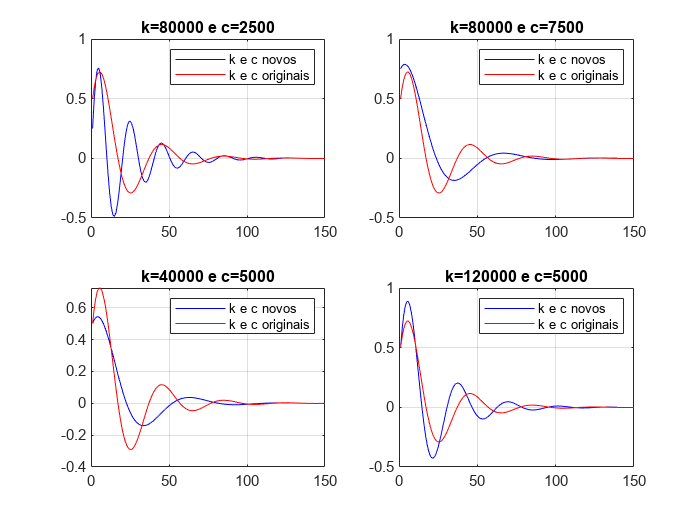

figure(3);
subplot(2,2,1)
p8 = plot(yimpulse1,'b');
hold on;
p9 = plot(yimpulse,'r');
grid
legend('k e c novos','k e c originais')
title('k=80000 e c=2500')

subplot(2,2,2)
p10 = plot(yimpulse2,'b');
hold on;
p11 = plot(yimpulse,'r');
grid
legend('k e c novos','k e c originais')
title('k=80000 e c=7500')

subplot(2,2,3)
p12 = plot(yimpulse3,'b');
hold on;
p13 = plot(yimpulse,'r');
grid
legend('k e c novos','k e c originais')
title('k=40000 e c=5000')

subplot(2,2,4)
p14 = plot(yimpulse4,'b');
hold on;
p15 = plot(yimpulse,'r');
grid
legend('k e c novos','k e c originais')
title('k=120000 e c=5000')

    Agora, analisando a transmissibilidade:

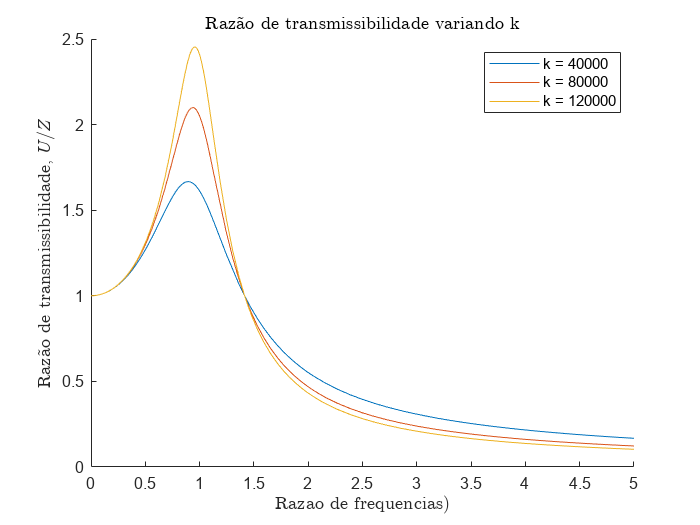

syms r
c = 5000;
ks = [40000 80000 120000];
figure
hold on
legend_str = strings(1, length(ks));
for i = 1:length(ks)
k = ks(i);
xi=c/(2*sqrt(k*m));
TR = sqrt((1+(2*xi*r)^2)/((1-r^2)^2+(2*xi*r)^2));
fplot(TR, [0 5])
 legend_str(i) = ['k = ', num2str(k)];
end
legend(legend_str);
title('Raz\~ao de transmissibilidade variando k','Interpreter','latex');
ylabel('Raz\~ao de transmissibilidade, $U/Z$','Interpreter','latex')
xlabel('Razao de frequencias)','Interpreter','latex')
hold off

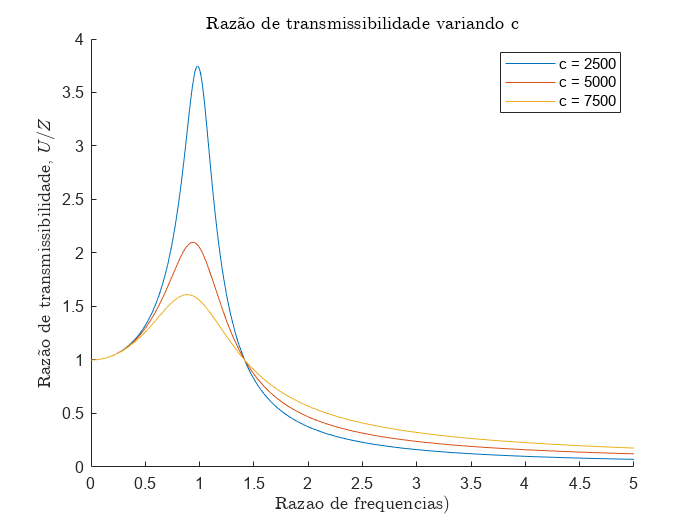



syms r
k = 80000;
cs = [2500 5000 7500];
figure
hold on
legend_str = strings(1, length(cs));
for i = 1:length(cs)
c = cs(i);
xi=c/(2*sqrt(k*m));
TR = sqrt((1+(2*xi*r)^2)/((1-r^2)^2+(2*xi*r)^2));
fplot(TR, [0 5])
 legend_str(i) = ['c = ', num2str(c)];
end
legend(legend_str);
title('Raz\~ao de transmissibilidade variando c','Interpreter','latex');
ylabel('Raz\~ao de transmissibilidade, $U/Z$','Interpreter','latex')
xlabel('Razao de frequencias)','Interpreter','latex')
hold off

## Propostas de parâmetros da suspensão que melhorem as respostas

    Para nosso projeto, quanto menor o ganho e menor o tempo de acomodaçao, melhor para a resposta do amortecedor, logo, é necessário equilibrar bem os valores de K e c. Logo, tanto c quanto K devem ser maiores. Foram escolhidos os valores:

m_projeto = 1000;
c_projeto = 7500;
k_projeto = 85000;

    Agora analisando o sistema: 

den_projeto = [m_projeto,c_projeto,k_projeto];
num_sis_projeto = [c_projeto,k_projeto];
sys_projeto = tf(num_sis_projeto,den_projeto)

sys_projeto =
 
       7500 s + 85000
  -------------------------
  1000 s^2 + 7500 s + 85000
 
Continuous-time transfer function.



yimpulse_projeto = 0.1*impulse(sys_projeto);

     E, então, para uma entrada impulsiva e a entrada de uma lombada senoidal, trapezoidal e parabólica:

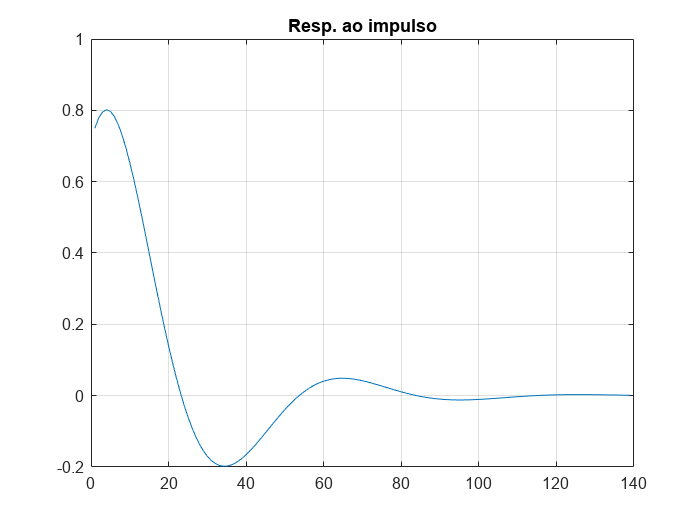

figure(4)
p16 = plot(yimpulse_projeto);
grid
title('Resp. ao impulso')

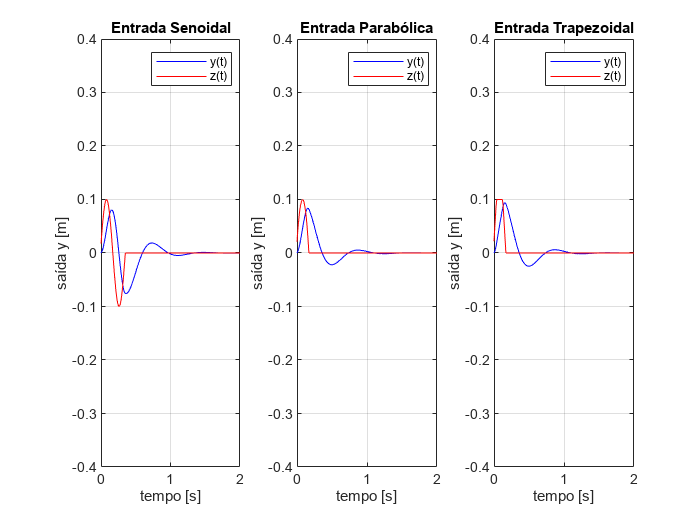


tlombada = [0.01:0.01:0.18];
tseno = [0.01:0.01:0.36];

zsen_projeto = [0.1*sin(2*pi()*tseno/0.36) zeros(1,length(t)-length(tseno))];
ysen_projeto = lsim(sys_projeto,zsen_projeto,t,x0);

figure(5);
subplot(1,3,1);
p17 = plot(t,ysen_projeto,"b");
hold on;
subplot(1,3,1);
p18 = plot(t,zsen_projeto,"r");
ylim([-0.4, 0.4]);
xlim([0, 2]);
grid
legend('y(t)','z(t)')
title('Entrada Senoidal')
xlabel('tempo [s]')
ylabel('saída y [m]')

zparab_projeto = [-20*tlombada.*(20*tlombada-3.6)*0.0308641976 ... 
    zeros(1,length(t)-length(tlombada))];
yparab_projeto = lsim(sys_projeto,zparab_projeto,t,x0);


subplot(1,3,2);
p19 = plot(t,yparab_projeto,"b");
hold on;
subplot(1,3,2);
p20 = plot(t,zparab_projeto,"r");
ylim([-0.4, 0.4]);
xlim([0, 2]);
grid
legend('y(t)','z(t)')
title('Entrada Parabólica')
xlabel('tempo [s]')
ylabel('saída y [m]')

ztrap_projeto = [0.1*trapmf(tlombada,[0 0.9/20 2.7/20 3.6/20]) ...
    zeros(1,length(t)-length(tlombada))];
ytrap_projeto = lsim(sys_projeto,ztrap_projeto,t,x0);

subplot(1,3,3);
p20 = plot(t,ytrap_projeto,"b");
hold on;
subplot(1,3,3);
p21 = plot(t,ztrap_projeto,"r");
ylim([-0.4, 0.4]);
xlim([0, 2]);
grid
legend('y(t)','z(t)')
title('Entrada Trapezoidal')
xlabel('tempo [s]')
ylabel('saída y [m]')

    E a transmissibilidade:

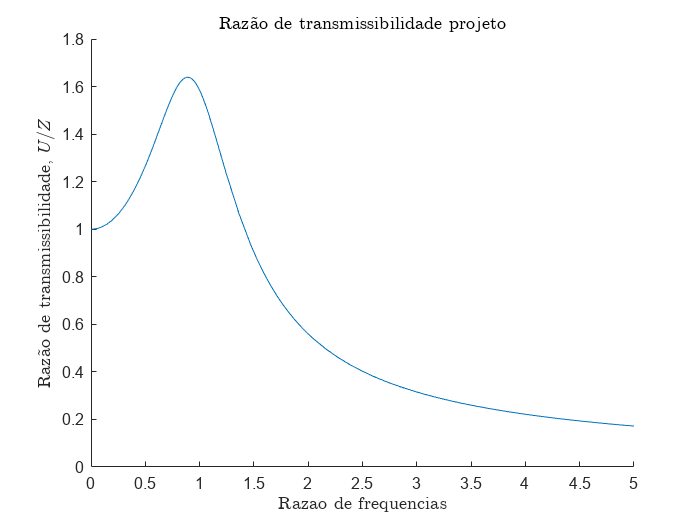

figure
hold on

xi=c_projeto/(2*sqrt(k_projeto*m_projeto));
TR = sqrt((1+(2*xi*r)^2)/((1-r^2)^2+(2*xi*r)^2));
fplot(TR, [0 5])

title('Raz\~ao de transmissibilidade projeto','Interpreter','latex');
ylabel('Raz\~ao de transmissibilidade, $U/Z$','Interpreter','latex')
xlabel('Razao de frequencias','Interpreter','latex')
hold off

    Logo, o projeto parece satisfatório!